# Descomposición espectral

## Importación

load("../../../Utils4SP/Datasets/S5_Estadistica101_LaVenganza.mat")


## Previsualización

- Stackedplot de Cassini

- Plot de buho

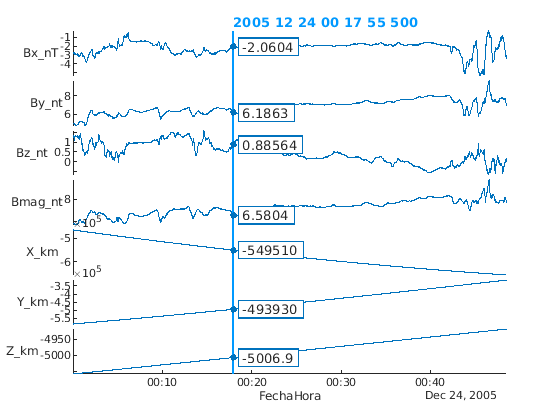

figure
stackedplot(Cassini,'XVariable','FechaHora')

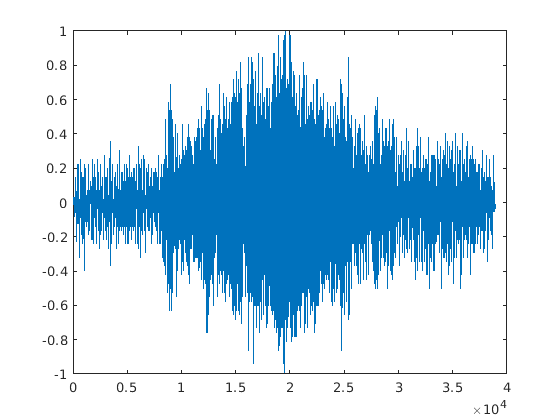


figure
plot(buho(:,1))

## FFT

- Hacer una señal sinusoidal discreta

- Plotearla

- FFT fft(señal) de la señal sinusoidal

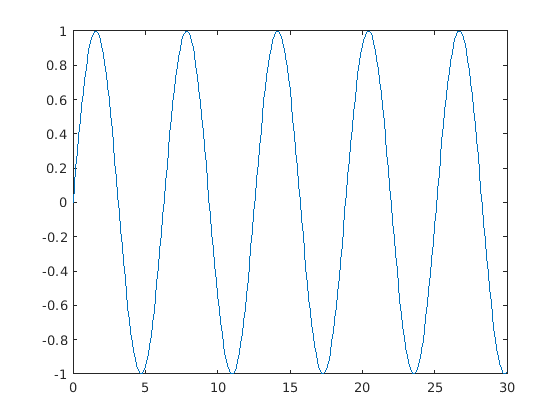

Ts=0.1;
fs=1/Ts;


t=0:Ts:30;
x=@(t) sin(t);
x_disc=x(t);
N=numel(x_disc);

figure
plot(t,x_disc)


X=fft(x_disc)

X = 	1.0e+02 *

   0.0796 + 0.0000i   0.0830 + 0.0211i   0.0954 + 0.0490i   0.1278 + 0.0997i   0.2518 + 0.2669i  -0.8323 - 1.1303i  -0.1267 - 0.2130i  -0.0611 - 0.1245i  -0.0370 - 0.0902i  -0.0248 - 0.0717i  -0.0175 - 0.0600i  -0.0127 - 0.0518i  -0.0094 - 0.0458i  -0.0070 - 0.0410i  -0.0051 - 0.0373i  -0.0037 - 0.0342i  -0.0026 - 0.0316i  -0.0017 - 0.0293i  -0.0009 - 0.0274i  -0.0003 - 0.0257i   0.0002 - 0.0243i   0.0007 - 0.0229i   0.0011 - 0.0217i   0.0014 - 0.0207i   0.0017 - 0.0197i   0.0019 - 0.0188i   0.0021 - 0.0180i   0.0023 - 0.0173i   0.0025 - 0.0166i   0.0027 - 0.0159i   0.0028 - 0.0153i   0.0029 - 0.0148i   0.0031 - 0.0143i   0.0032 - 0.0138i   0.0033 - 0.0133i   0.0033 - 0.0129i   0.0034 - 0.0125i   0.0035 - 0.0121i   0.0036 - 0.0117i   0.0036 - 0.0114i   0.0037 - 0.0111i   0.0037 - 0.0108i   0.0038 - 0.0105i   0.0038 - 0.0102i   0.0039 - 0.0099i   0.0039 - 0.0097i   0.0040 - 0.0094i   0.0040 - 0.0092i   0.0040 - 0.0089i   0.0041 - 0.0087i


- plot de X

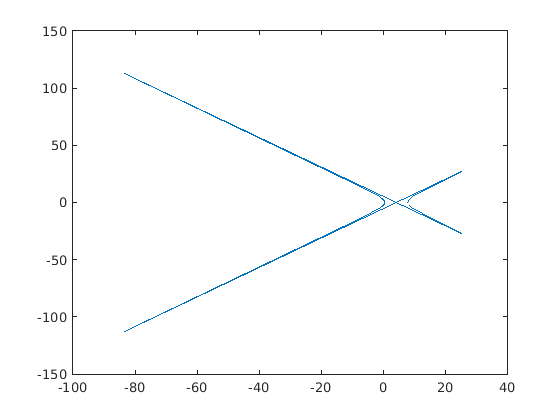

figure
plot(X)

- Plotear la magnitud de X abs()

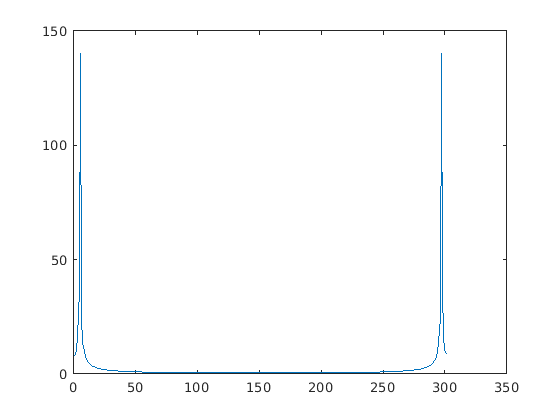

figure
plot(abs(X))

- Plotear la magnitud al cuadrado

- Guardar la magnitud al cuadrado en una variable que se llame "Densidad de Energía" o "energyDensity"

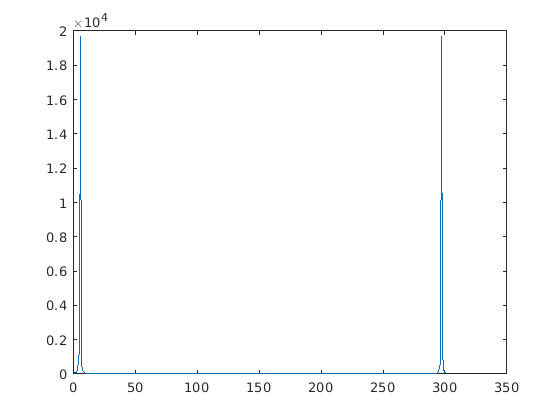

energyDensity=abs(X).^2;
figure
plot(energyDensity)

- Calcular la densidad de potencia espectral 

- Guardarla en una variable llamada "powerDensity"

- Plotearla

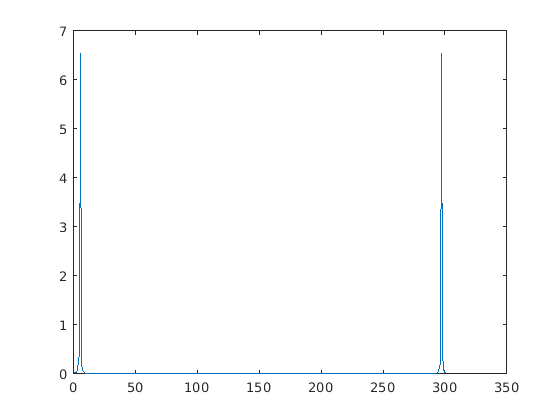

powerDensity=energyDensity./(N.*fs);
plot(powerDensity)

- Plotear esta cantidad en decibeles

- 
$$Power \quad dB=10log_{10}(PSD)$$


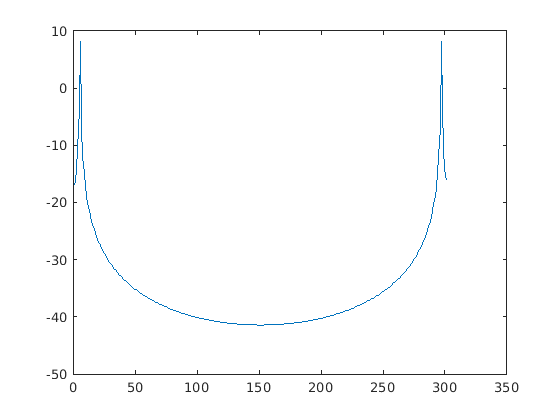

figure
plot(10.*log10(powerDensity))

- Tomar únicamente la mitad de las muestras de "densidad de energía" y de ella calcular la potencia.

- Crear las variables N_energySpectrum

- Plotearla en Power dB

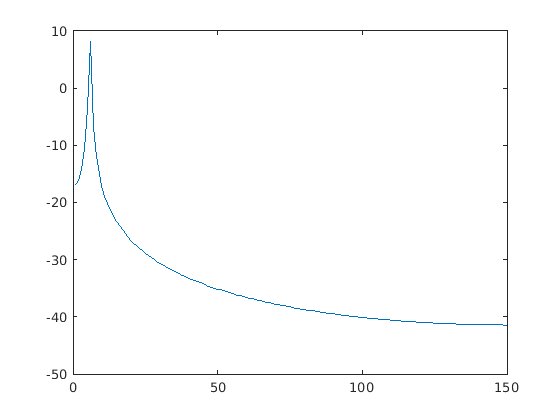

energyDensity=energyDensity(1:floor(N/2));
N_energySpectrum=numel(energyDensity);
powerDensity=energyDensity./(N.*fs);

figure
plot(10.*log10(powerDensity))

## Eje de frecuencias

%Teorema de Nyquist: f_max<fs/2
%Frecuencia de Nyquist
f_Nyquist=fs/2

f_Nyquist = 5


%Resolución en frecuencia
%Df=fs/N
Df=fs/N_energySpectrum

Df = 0.0667


%Nota: fs alta
% + randog dinámico
% - resolución

f=(0:N_energySpectrum-1)./(N_energySpectrum).*f_Nyquist;


## Contenido espectral con brillitos

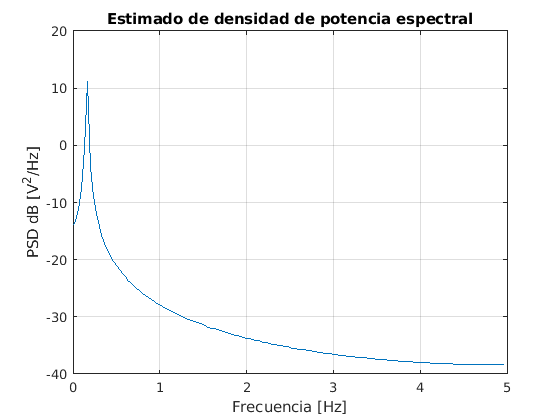

figure
%plot(f,10.*log10(powerDensity))
plot(f,pow2db(2.*powerDensity))
title("Estimado de densidad de potencia espectral")
xlabel("Frecuencia [Hz]")
ylabel("PSD dB [V^2/Hz]")
grid on

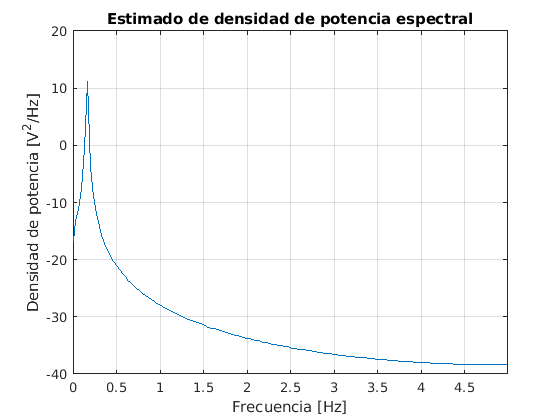


figure
periodogram(x_disc,[],N,fs)
ylabel("Densidad de potencia [V^2/Hz]")
xlabel("Frecuencia [Hz]")
title("Estimado de densidad de potencia espectral")

## Periodogram para el buho

- Usar periodogram para el buho

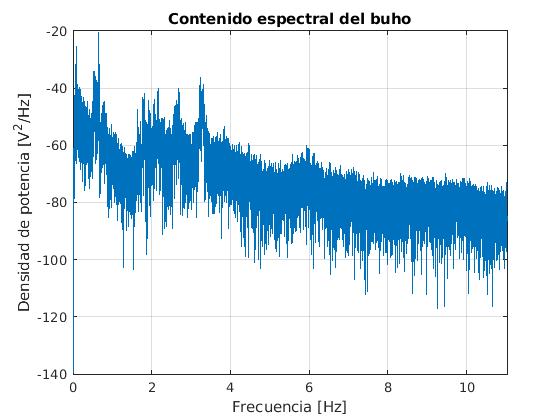

buho_left=buho(:,1);
N_buho=numel(buho_left);

figure
periodogram(buho_left,[],N_buho,fs_buho)
ylabel("Densidad de potencia [V^2/Hz]")
xlabel("Frecuencia [Hz]")
title("Contenido espectral del buho")

## Sacar datos del periodograma

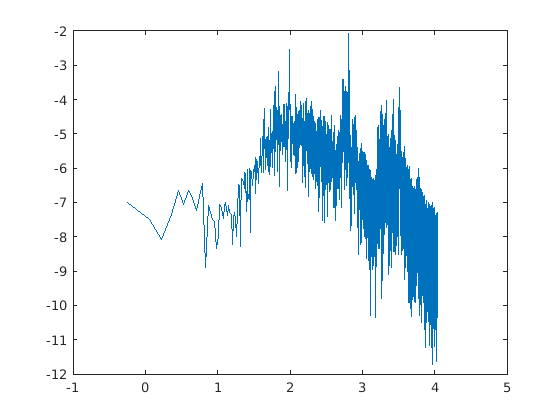

buho_left=buho(:,1);
N_buho=numel(buho_left);


[Pxx,F]=periodogram(buho_left,[],N_buho,fs_buho);


figure
plot(log10(F),log10(Pxx))

## Espectrograma

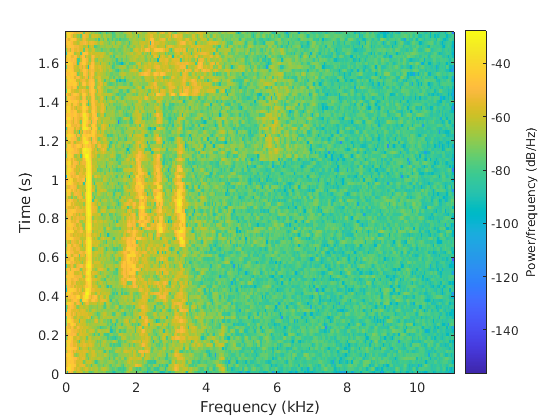

%Aguas con la RAM
N_spectrogram=round(N_buho/100);



figure
spectrogram(buho_left,N_spectrogram,0,[],fs_buho)